p = 50; % dimensionality of each datapoint
N = 500; % number of datapoints

X = randn(p,N); %p-dimensional datapoints, we have N datapoints

% Zero-mean the data by subtracting the mean of the dataset from each datapoint.
mu_X = mean(X);
zero_mean_X = X - mu_X

zero_mean_X =     0.8897   -0.4610   -0.6101    1.0859    2.1357   -0.0151    0.6152    0.0052   -1.0210   -0.8411    0.4013   -0.8012    0.0500   -1.1911   -0.6765    0.1393    1.3759    0.7634   -0.3713   -0.7180    0.0841    0.6833   -0.6784   -1.2718   -1.9952   -0.7663    0.2472   -0.2652    0.9711   -1.2581   -0.8602   -0.2076    0.9648    1.4884    1.7368    1.1670   -0.9218    0.6463    1.5113    0.4609    1.4835   -0.7785    1.0042    0.9272    0.8192    0.4108    0.4796   -0.8128    0.2740   -0.9827
   -1.2772    0.5180    0.3613    1.0551   -0.7110   -1.8253   -1.0264   -0.5644    0.3626   -0.2270    2.0790   -2.7672   -2.1729    1.2184   -1.0697   -0.4646   -0.0364    0.2345   -0.7524   -0.6650    0.1772   -0.3991    0.4696   -0.8354   -0.7948    0.5509    0.3734    1.8855    0.4479    0.3469   -0.7239    0.8479    0.6708   -0.8454    1.2546   -0.7508   -0.1410    0.9087   -0.7222   -1.2380   -0.8233    0.4129    0.4488   -1.5469    0.6623   -0.6021    1.2154    0.6765   -0


% Calculate the p × p dimensional covariance matrix of the zero-mean dataset.
covariance_matrix = cov(zero_mean_X');

% Calculate the eigenvectors (VX_1) and eigenvalues (DX_1) of this covariance matrix.
q1 = 50;
[VX_1,DX_1] = eigs(covariance_matrix,q1);
diag_DX_1 = diag(DX_1);

% Sum of all p eigenvalues
Sum_eigenvalues_X_1 = sum(diag_DX_1) 

Sum_eigenvalues_X_1 = 49.3020


% D: contains the q largest eigenvalues in the matrix
% V: p × q matrix containing the corresponding eigenvectors of the square covariance matrix

% q: reduced dimensionality - How do we decide this number? 
% By trying different values and observing how close the sum of the eigenvalues is to the sum of all p eigenvalues
Sum_eigenvalues_X_2 = [];
for q2 = 1:1:50 
    [VX_2,DX_2] = eigs(covariance_matrix,q2) ;
    diag_DX_2 = diag(DX_2);
    Sum_eigenvalues_X_2 = [Sum_eigenvalues_X_2 sum(diag_DX_2)];
end

VX_2

VX_2 =     0.0347   -0.1152   -0.1125   -0.2513    0.0174   -0.2623    0.2057   -0.0990    0.0525    0.2830    0.0982    0.0172   -0.1537    0.1890   -0.0864    0.0389   -0.0742   -0.0398    0.1474    0.1833   -0.1765   -0.4297   -0.0390   -0.0226   -0.0946    0.1306    0.0122    0.0640   -0.0723    0.0265   -0.0338   -0.1149   -0.2213   -0.0170   -0.2326   -0.1318   -0.0225   -0.1231   -0.0473   -0.1917   -0.2294   -0.0308   -0.0752   -0.0905    0.1320    0.0355    0.0919    0.0774   -0.0264    0.1414
   -0.1291    0.0682    0.0001    0.1104   -0.1100   -0.2019   -0.2347   -0.2084   -0.0839    0.1253   -0.0583   -0.2857   -0.0176    0.0243   -0.1410    0.0903    0.2417   -0.0416   -0.2503    0.0334    0.0074    0.1831    0.1671   -0.0749   -0.0320   -0.1192   -0.0263    0.0835   -0.0297    0.2089   -0.2111   -0.1528    0.0917    0.0434   -0.0971    0.2309   -0.2298   -0.0910    0.0442   -0.1442   -0.1131   -0.0394    0.0969   -0.0119    0.1980    0.1429    0.0493   -0.0196    0.2981  

DX_2

DX_2 =     1.7156         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    1.5823         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0  

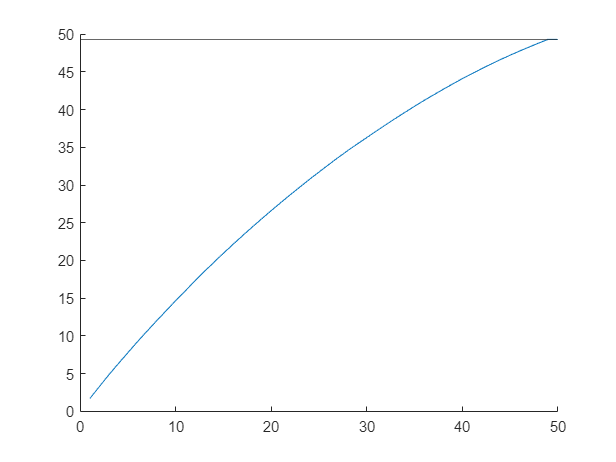


yline(Sum_eigenvalues_X_1)
hold on
plot(Sum_eigenvalues_X_2)


% Conclusion: the greater the q value (reduced dimensionality) , the closer
% the sum of the eigenvalues produced to the sum of eigenvalues of all p eigenvalues

% Decision for new dimensionality
q = 40;

% Create the q × p projection matrix ET from the eigenvectors corresponding to the q largest eigenvalues, 
% and reduce the dataset by multiplying it with this matrix.
Et = VX_1(1:q,:);
Z = Et*zero_mean_X

Z =    -0.4484    0.7969   -0.5083    0.9701    0.3203    1.5602   -0.5670    0.0701    0.3079    0.6046   -0.4229    1.3433    2.0321    0.1436    0.1200    0.0184    0.4923   -0.6618    0.8184   -1.3170   -0.3913    0.1062    0.3409   -0.4567   -0.5148   -0.7772    1.1860    0.3766    0.3189   -0.5773   -1.0197    0.7159   -0.5324    0.2556   -0.2441   -1.9380    1.6858   -0.5531    0.4880   -0.3584    1.1762    1.3760    0.1259    0.9965   -0.6194    1.7254   -1.4149    0.0296    1.7028   -0.6176
   -1.0021   -0.0217   -0.2084   -0.0801    0.4452   -1.5693   -0.9004   -0.9730    1.1209   -1.2349   -0.7044   -0.7281   -0.2955    1.7136   -0.4016    1.3339    0.2350   -1.2936    0.0431   -0.2891    0.6446   -2.8460    1.5040    0.4849    0.0960    1.9816    0.8201    1.2014    0.8460   -0.0475    0.1061   -0.5427    0.8946    0.1214    0.6212   -0.6218   -0.7716   -2.9226    1.1177   -0.9280   -0.3980   -0.6050    0.4451    0.2857    0.0307   -0.4458   -0.6250    0.1785    1.1137    2

To obtain the corresponding *p*-dimensional datapoints multiply the new data with the transpose of the projection matrix.

Notice that this corresponds to choosing *F *in (2) such that *F *= *E*. If *q *is well chosen these regenerated datapoints should

be fairly similar to the original datapoints, thus capturing most of the information in the dataset. Remember to add the

mean again when comparing with the original data instead of the zero-mean data.

F = Et'; 
X_hat = F*Z

X_hat =     0.1828   -0.2341   -0.9357    1.0084    0.6209   -0.5891   -0.1658   -0.2343   -0.2745   -0.3315   -0.5178   -0.3595    0.5483   -0.5110   -1.3768   -0.4625    0.9853    0.0605   -0.3176    0.2120   -0.9943    0.8670   -0.9761   -0.5873   -1.3344    0.0260   -0.6852   -0.5999    1.2710   -0.6286   -0.5175   -1.0711    0.9126    1.6420    0.1284   -0.1868   -0.7842    0.7901    0.5565    0.8275    0.7533   -0.5808    0.4293    1.4507    0.7637   -0.5258    0.1583   -0.7729   -0.2153   -1.2733
   -1.4817    0.7397   -0.0983    0.9361   -0.6428   -2.1946   -1.0797   -0.9095    0.4531   -0.1656    1.9448   -2.4647   -2.2086    1.4541   -0.5141   -0.6802   -0.2582   -0.2601   -0.6526   -0.5431    0.2589   -0.2699    0.3023   -0.6139   -0.5259    0.5333    0.4290    1.2004    0.2758    0.3470   -0.4737    1.1197    0.7695   -1.0282    1.4837   -0.7778   -0.3198    0.9674   -0.7956   -1.2123   -0.5719    0.8886    0.4784   -1.0514    0.3604   -1.1635    1.0852    1.0335   -0.7443 

The X_hat values are the same as zero_mean_X for reduced dimensionality = 50. For lower q values, the values diverge more as q decreases.